Check for Bluetooth Device

 
blelist

Run bluetoothlist to search for nearby Bluetooth classic devices.


ans = 8×5 table
    Index    Name       Address        RSSI    Advertisement
    _____    ____    ______________    ____    _____________

      1       ""     "561C16B46769"    -56      1×1 struct  
      2       ""     "EAE00D961BF5"    -66      1×1 struct  
      3       ""     "568187BD41BF"    -76      1×1 struct  
      4       ""     "0946874F861A"    -81      1×1 struct  
      5       ""     "737E87369546"    -82      1×1 struct  
      6       ""     "66666673291D"    -85      1×1 struct  
      7       ""     "4A4221CC3670"    -88      1×1 struct  
      8       ""     "6C33A8F4FBAF"    -88      1×1 struct  


Connect to Bluetooth

 
% Create a BLE object and connect to the device
clc
clear all
close all
name = "BLE_Matlab";
bt = ble(name); 
c = characteristic(bt,"EF680201-9B35-4933-9B10-52FFA9740042","EF680202-9B35-4933-9B10-52FFA9740042");
pause(0.5);

Graph Data

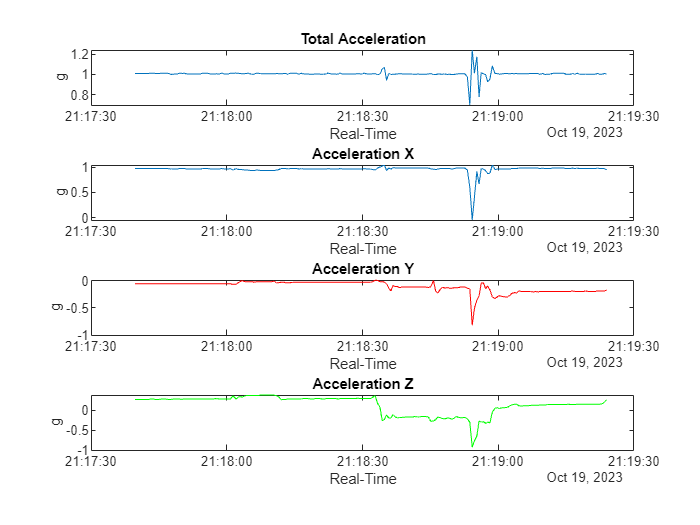

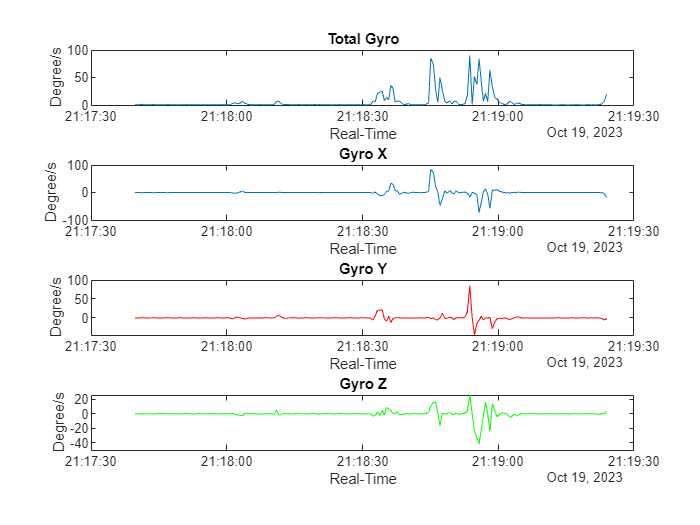

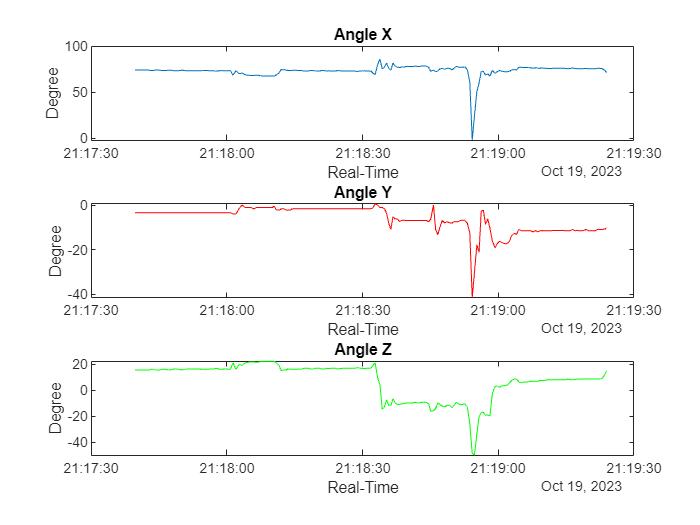

  
Num_Step = 200;
close all;

% Define regular expressions for capturing numeric values
accelXPattern = 'Acceleration Xa:\s*(-?\d+\.\d+)';
accelYPattern = 'Ya:\s*(-?\d+\.\d+)';
accelZPattern = 'Za:\s*(-?\d+\.\d+)';
rotationXPattern = 'Rotation Xg:\s*(-?\d+\.\d+)';
rotationYPattern = 'Yg:\s*(-?\d+\.\d+)';
rotationZPattern = 'Zg:\s*(-?\d+\.\d+)';

accelX = zeros(Num_Step, 1);
accelY = zeros(Num_Step, 1);
accelZ = zeros(Num_Step, 1);
rotationX = zeros(Num_Step, 1);
rotationY = zeros(Num_Step, 1);
rotationZ = zeros(Num_Step, 1);
temperature = zeros(Num_Step, 1);
thetaX = zeros(Num_Step, 1);
thetaY = zeros(Num_Step,1);
thetaZ = zeros(Num_Step, 1);

times = datetime.empty(Num_Step, 0);

% Initialize a loop counter
loopCount = 0;
% Read lines from the serial port
while loopCount < Num_Step
    data = read(c);
    textData = char(data);
    check_val = isempty(regexp(textData, accelXPattern, 'tokens', 'once'));
    % Extract values using regular expressions
    if check_val
        continue;
    end
    loopCount = loopCount + 1;
    times(loopCount) = datetime("now");
    accelX(loopCount) = str2double(regexp(textData, accelXPattern, 'tokens', 'once'));
    accelY(loopCount) = str2double(regexp(textData, accelYPattern, 'tokens', 'once'));
    accelZ(loopCount) = str2double(regexp(textData, accelZPattern, 'tokens', 'once'));
    rotationX(loopCount) = str2double(regexp(textData, rotationXPattern, 'tokens', 'once'));
    rotationY(loopCount) = str2double(regexp(textData, rotationYPattern, 'tokens', 'once'));
    rotationZ(loopCount) = str2double(regexp(textData, rotationZPattern, 'tokens', 'once'));

    accel_val(loopCount) = sqrt(accelX(loopCount)^2+accelY(loopCount)^2+accelZ(loopCount)^2);
    total_gyro(loopCount)= sqrt(rotationX(loopCount)^2+rotationY(loopCount)^2+rotationZ(loopCount)^2);

    thetaX(loopCount) = rad2deg(asin(accelX(loopCount)/accel_val(loopCount)));
    thetaY(loopCount) = rad2deg(asin(accelY(loopCount)/accel_val(loopCount)));
    thetaZ(loopCount) = rad2deg(asin(accelZ(loopCount)/accel_val(loopCount)));

    
    
    % Subplot for Total Acceleration
    figure(1);
    subplot(4, 1, 1);
    plot(times(1:loopCount), accel_val(1:loopCount));
    title("Total Acceleration");
    xlabel("Real-Time");
    ylabel("g");

    subplot(4, 1, 2);
    plot(times(1:loopCount), accelX(1:loopCount));
    title("Acceleration X");
    xlabel("Real-Time");
    ylabel("g");

    % Subplot for Acceleration X Y Z
    subplot(4, 1, 3);
    plot(times(1:loopCount), accelY(1:loopCount),'r');
    title("Acceleration Y");
    xlabel("Real-Time");
    ylabel("g");

    % Subplot for Gyro X Y Z
    subplot(4, 1, 4);
    plot(times(1:loopCount), accelZ(1:loopCount),'g');
    title("Acceleration Z");
    xlabel("Real-Time");
    ylabel("g");

    % Subplot for Total Acceleration
    figure(2);
    subplot(4, 1, 1);
    plot(times(1:loopCount), total_gyro(1:loopCount));
    title("Total Gyro");
    xlabel("Real-Time");
    ylabel("Degree/s");

    subplot(4, 1, 2);
    plot(times(1:loopCount), rotationX(1:loopCount));
    title("Gyro X");
    xlabel("Real-Time");
    ylabel("Degree/s");

    % Subplot for Acceleration X Y Z
    subplot(4, 1, 3);
    plot(times(1:loopCount), rotationY(1:loopCount),'r');
    title("Gyro Y");
    xlabel("Real-Time");
    ylabel("Degree/s");

    % Subplot for Gyro X Y Z
    subplot(4, 1, 4);
    plot(times(1:loopCount), rotationZ(1:loopCount),'g');
    title("Gyro Z");
    xlabel("Real-Time");
    ylabel("Degree/s");

    % Subplot for Total Acceleration
    figure(3);
    subplot(3, 1, 1);
    plot(times(1:loopCount), thetaX(1:loopCount));
    title("Angle X");
    xlabel("Real-Time");
    ylabel("Degree");

    % Subplot for Acceleration X Y Z
    subplot(3, 1, 2);
    plot(times(1:loopCount), thetaY(1:loopCount),'r');
    title("Angle Y");
    xlabel("Real-Time");
    ylabel("Degree");

    % Subplot for Gyro X Y Z
    subplot(3, 1, 3);
    plot(times(1:loopCount), thetaZ(1:loopCount),'g');
    title("Angle Z");
    xlabel("Real-Time");
    ylabel("Degree");
    
   pause(0.05);
end

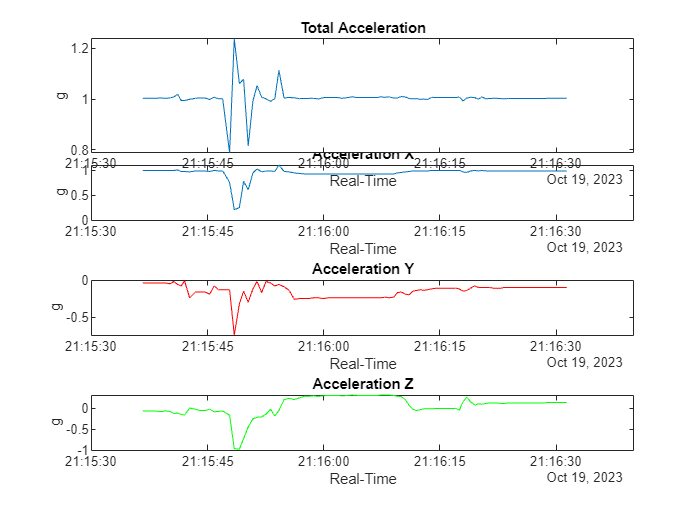


% Create a single figure with multiple subplots
figure(1);

% Subplot for Total Acceleration
subplot(3, 1, 1);
plot(times, accel_val);
title("Total Acceleration");
xlabel("Real-Time");
ylabel("g");

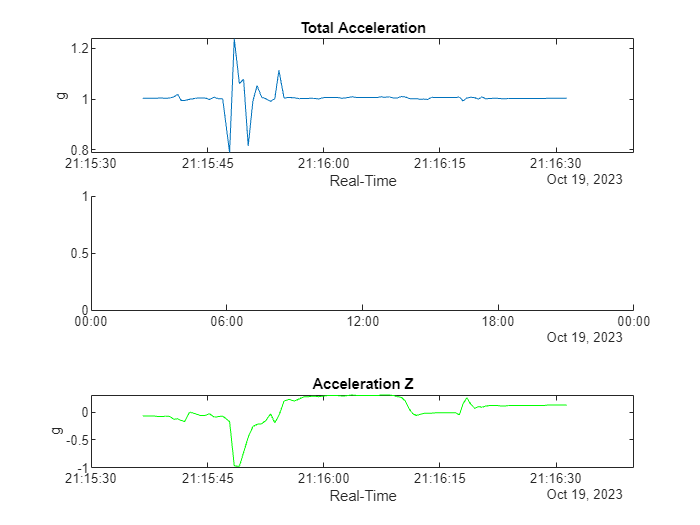

Error using plot
Vectors must be the same length.


% Subplot for Acceleration X Y Z
subplot(3, 1, 2);
hold on
plot(times, accelX);

plot(times, accelY);
plot(times, accelZ);
hold off
title("Acceleration X Y Z");
xlabel("Real-Time");
ylabel("g");

% Subplot for Gyro X Y Z
subplot(3, 1, 3);
hold on
plot(times, rotationX);
plot(times, rotationY);
plot(times, rotationZ);
hold off
title("Gyro X Y Z");
xlabel("Real-Time");
ylabel("Degree/s");